Филимонов Степан РЛ6-31

Лабараторная номер 1

Задача:

В момент времени t = 0 волновая функция, описывающая квантовое состояние микрочастицы, движущейся вдоль оси х имеет вид: 

(x,0)=A * (exp(-) + ibx) 

Здесь: A,a,b - известные действительные константы. 

Определить зависимости от координаты х: 

а) действительной части волновой функции; 

b) квадрата модуля волновой функции. 

Построить эти зависимости. 

Теория: 

Формула Эйлера связывает комплексную экспоненту с тригонометрическими  функциями. Она утверждает, что для любого вещественного числа x  выполнено следующее равенство: 

 = cos(x) + i * sin(x). 

Тогда решение:

y = A*exp((-x^2)/(a^2))*(cos(b*x) + i*sin(b*x))

Код MatLab:


$$\varphi_{\mathbf{встр}} ={20}^0$$


cla reset;
A = 5;
a = 2.2;
b = 4;
x = linspace(-5,5,100);
i = sqrt(-1);
Psis = A.*exp((-x.^2)/(a^2)).*(cos(b*x) + i*sin(b*x));
PsisReal = real(Psis);
PsisAbs = abs(Psis.^2);
hold on;
plot( x, PsisReal,"LineWidth",3.5,"Color",'red',"LineStyle","--");
plot( x, Psis, "LineWidth", 2,"LineStyle","-","Color",'blue');

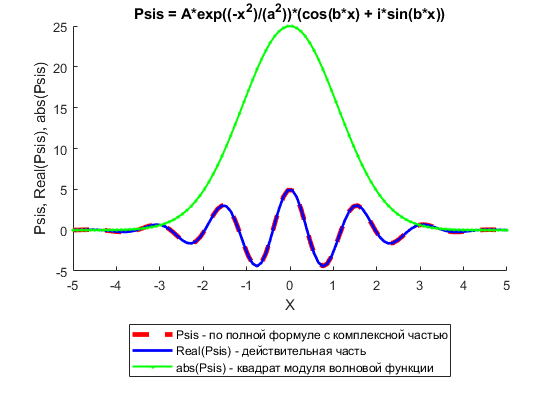

% уточнение: Matlab подчеркивет это потому что автоматически произвел такую
% операцию Psis -> real(Psis) , в следствии чего комплексные значения
% не учитывались
plot( x, PsisAbs,"Marker",".","LineStyle","-","Color",'green',"LineWidth",1.5);
xlabel('X');
ylabel('Psis, Real(Psis), abs(Psis)');
title('Psis = A*exp((-x^2)/(a^2))*(cos(b*x) + i*sin(b*x))'); % Не точная формула
legend('Psis - по полной формуле с комплексной частью','Real(Psis) - действительная часть','abs(Psis) - квадрат модуля волновой функции','Location',"southoutside");